## **CIV102 Bridge Design Script - MATLAB Calculations**

**By: Matthew Oliveira, Joyce Shen, Andy Cai**

**-----------------------------------------------------------------------------------------------------------------**

**Initializing the Dimensions of the Bridge**

n = 1250;       %Number of locations to evaluate bridge failure
L = 1250;       %Length of the bridge

x = linspace(0, L, n);  %Defining a coordinate system to describe the bridge
SFD_PL = zeros(1, n);   %Defining a matrix to hold the shear force at any point being checked
force_profile = zeros(1, n);

dimensional_profile = ones(n, 5); % Should be formatted as height, width_bottom, width_top, LayersTop, LayersBot
for b = 1:n
    dimensional_profile(b, 1) = 120;
    dimensional_profile(b, 2) = 50;
    dimensional_profile(b, 3) = 70;
    dimensional_profile(b, 4) = 1;
    dimensional_profile(b, 5) = 1;
end

**We can use the function ApplyPL to generate our SFD and BMD and plot these (to test)**

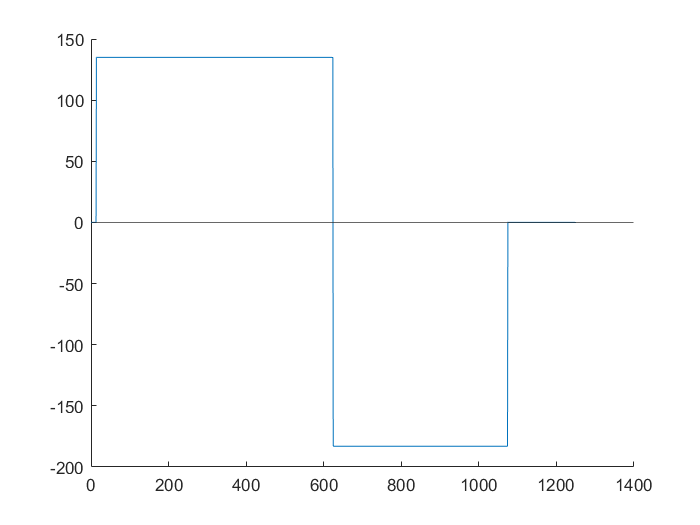

P = 318; 
[SFD, BMD, force_profile] = ApplyPL(625, P, x, force_profile);      % Construct SFD, BMD 

figure
hold on;
plot(x,SFD)
yline(0)
hold off;

**We can use the function SectionProperties to analyze the cross-section of a bridge defined with the properties given in the matrix**


[I, y, Q, QGlue] = SectionProperties(dimensional_profile(1,:))

I = 3.0287e+06

y = 63.3453

Q = 2.2003e+04

QGlue = 4.9802e+03

**Defining Functions to Apply Loads to the Bridge and Solve for Reaction Forces and Generate BMD, and force_profile**

function [SFD, BMD, force_profile] = ApplyPL(xP, P, x, fs_I)
% Constructs SFD and BMD from application of 1 Point Load. Assumes fixed location of supports 
% Input: location and magnitude of point load. The previous SFD can be entered as input to  
%  construct SFD of multiple point loads 
% Output: SFD, BMD both 1-D arrays of length n 

%We make a vector to act as a temporary container for our downward forces
%and the reaction forces
force_profile = -1 .* fs_I;

%For the force profile, a positive sign will represent a downward force,
%which will be changed after when converting to the SFD and BMD

%We then add the point load to SFD at the position indicated
force_profile(xP) = P;

%We then solve for the reaction forces
support_A_position = 15;
support_B_position = 1075;

%Because the sum of the moments must be equal to zero:

moment_about_A = 0;

for pos = support_A_position:1250
   if force_profile(pos) ~= 0
       moment_about_A = moment_about_A + (pos-support_A_position) * force_profile(pos);
   end
end

force_at_B = -1 .* moment_about_A / (support_B_position - support_A_position);

force_profile(support_B_position) = force_at_B;

%Because the sum of the forces in the y-direction must sum to zero:

remaining_downward_force = 0;

for pos = support_A_position:1250
    if force_profile(pos) ~= 0
        remaining_downward_force = remaining_downward_force + force_profile(pos);
    end
end

force_at_A = -1 * remaining_downward_force;

force_profile(support_A_position) = force_at_A;

%The force profile is inverted at the end
force_profile = force_profile .* -1;

SFD = x .* 0;
BMD = x .* 0;

for pos = 2:1250
    
    if SFD(pos - 1) ~= 0
        if force_profile(pos) == 0
            SFD(pos) = SFD(pos-1);
        else
            SFD(pos) = SFD(pos-1) + force_profile(pos);
        end
    else
        if force_profile(pos) == 0
            SFD(pos) = SFD(pos-1);
        else
            SFD(pos) = SFD(pos-1) + force_profile(pos);
        end
    end
    
end

for pos = 2:1250
    
    BMD(pos) = BMD(pos-1) + SFD(pos);
end

end


**We will define a function that allows us to analyze section properties at a point**

function [I, y, Q, QGlue] = SectionProperties(inputMatrix)
% Input: Geometric Inputs. Format will depend on user 
% Output: Sectional Properties at every value of x. Each property is a 1-D array of length n

%first we will make matrices to represent the height and width of the
%smaller rectangles

height = inputMatrix(1);
width_bottom = inputMatrix(2);
width_top = inputMatrix(3);
LayersTop = inputMatrix(4);
LayersBot = inputMatrix(5);

baseRect = [1.27 * LayersBot, width_bottom];
verticalRect = [height - 1.27 * LayersBot - 1.27 * LayersTop, 1.27];
TopRect = [1.27 * LayersTop, width_top];


%First we find the Inertia and y of each subsection of the cross-section
I1 = (baseRect(1) * baseRect(2).^3) / 12;
y1 = (baseRect(1) / 2);
A1 = baseRect(1) .* baseRect(2);

I2 = 2 * (verticalRect(1) * baseRect(2).^3)/12;
y2 = verticalRect(1)/2 + baseRect(1);
A2 = 2 * (verticalRect(1) .* verticalRect(2));

I3 = (TopRect(1) .* TopRect(2).^3)/12;
y3 = (TopRect(1)/2) + baseRect(1) + verticalRect(1);
A3 = (TopRect(1) .* TopRect(2));

%We can now calculate the section properties
y = (A1 * y1 + A2 * y2 + A3 * y3)/(A1 + A2 + A3);

I = (I1 + (y - y1).^2 * A1 + I2 + (y - y2).^2 * A2 + I3 + (y-y3).^2 * A3);



Q = 2 .* (3 * verticalRect(1) / 2 + baseRect(1) - y) * (1.27 * verticalRect(1)/2) + (y3 - y) * A3;
QGlue = (y3 - y) * A3;

end


**We want a function that will tell us the shear force that would result in failure at every point from a shear failure:**